clear
% simultion of 6 metagriding

## constants


eta = 377; %ohm
f= 10*10^9; %Hz
c = 3*10^8; %m/s
lambda = c/f;
k = 2*pi/lambda;
omega = 2*pi*f;
w = 3*0.0254e-3; % meters, 3 mil
reff = w/4;
epsilon=8.85e-12;


## paramters


theta_in = 10*pi/180; %rads
theta_out = 70*pi/180;% rads
phi = 25*pi/180; % rads
Ein = 1;

sinin = sin(theta_in);
cosin = cos(theta_in);
sinout = sin(theta_out);
cosout = cos(theta_out);

Zin = eta/cos(theta_in);
Zout = eta/cos(theta_out);
Eout = Ein*sqrt(cosin/cosout);
Lambda = lambda/abs(sinout-sinin);

deltaRes=18.3e-3*eta/lambda; %resistence of copper wire

## Optimization parameters

numOfIter=100;% how maney random starting conditions to check
N=1000; % to what degree to calculate the infinate sums 
weigt=0.5;%how much to consider power lost and how much 
save('var.mat');
best.Zs=zeros(6,1);% the best results with only capacitance tipe impidances
best.PowerLost=inf;
best.CopperPowerLost=inf;
best.Ds=zeros(1,6);
best.Hs=zeros(1,6);
best.Is=FindCurrents(best.Ds,best.Hs,Lambda,Ein,Eout,Zin,Zout,theta_in,theta_out,k,phi);

## Optimization

i=1; %index
total=0;% for percentage of good ones
while i<=numOfIter 
    total=total+1;
    % initial position
    x0=[Lambda*rand(1,5),lambda*rand(1,5)];
    Ds= [0 x0(1:5)];
    Hs= [0 x0(6:10)];
    Is =  FindCurrents(Ds,Hs,Lambda,Ein,Eout,Zin,Zout,theta_in,theta_out,k,phi);
    Fields = FindElectricFiield(Lambda,k,eta,theta_in,theta_out,Ein,Ds,Hs,Is,reff,N,'Poisson');
    Zs = Fields./Is;
    if imag(Zs)<0
        % Set nondefault solver options
        options = optimoptions('fmincon','Display','off');
        
        % Solve
        [solution,objectiveValue] = fmincon(@objectiveFcn,x0,[],[],[],[],[],[],...
            @constraintFcn,options);
        
        % Clear variables
        clearvars options
        Ds = [0 solution(1:5)];
        Hs = [0 solution(6:10)];
        Is =  FindCurrents(Ds,Hs,Lambda,Ein,Eout,Zin,Zout,theta_in,theta_out,k,phi);
        Fields = FindElectricFiield(Lambda,k,eta,theta_in,theta_out,Ein,Ds,Hs,Is,reff,N,'Poisson');
        Zs = Fields./Is;
        objective = objectiveFcn(solution)
        if imag(Zs)<0
             i=i+1%go on with the index
        end
        if objective<best.PowerLost+weigt*best.CopperPowerLost % is it the best result so far?
            
          if imag(Zs)<0
              best.PowerLost=1/2*(abs(Is).^2).*real(Zs);
              best.CopperPowerLost=1/2*abs(Is).^2*deltaRes;
              best.Ds=[0,solution(1:5)];
              best.Hs=[0,solution(6:10)];
              best.Is=FindCurrents(best.Ds,best.Hs,Lambda,Ein,Eout,Zin,Zout,theta_in,theta_out,k,phi);
              best.Zs=FindElectricField(Lambda,k,eta,theta_in,theta_out,Ein,best.Ds,best.Hs,best.Is,reff,N,'Poisson')./best.Is;
          end
        end
    end
end

objective = 1.5646e-06

i = 2

objective = 1.7385e-04

objective = 5.6595e-05

objective = 1.0105e-04

objective = 5.8399e-05

objective = 9.5300e-05

i = 3

objective = 1.2636e-04

objective = 1.2490e-05

i = 4

objective = 5.8030e-05

objective = 2.1475e-06

objective = 2.1989e-04

objective = 4.2842e-05

objective = 7.6815e-05

objective = 4.2546e-04

i = 5

objective = 4.2299e-05

i = 6

objective = 4.8533e-05

objective = 6.5338e-05

objective = 7.4322e-05

objective = 1.2738e-06

objective = 3.5205e-05

objective = 2.7877e-06

objective = 6.8296e-06

objective = 8.9657e-05

objective = 3.5127e-05

objective = 5.5180e-05

objective = 1.0017e-04

objective = 5.1857e-05

objective = 2.6971e-04

i = 7

objective = 2.1743e-04

objective = 1.9647e-05

objective = 6.1596e-06

objective = 6.8148e-06

objective = 7.9431e-05

objective = 1.4530e-06

objective = 1.6291e-04

i = 8

objective = 1.6150e-04

objective = 8.9422e-05

i = 9

objective = 3.3328e-05

objective = 6.1469e-05

objective = 7.1035e-05

objective = 1.3840e-04

i = 10

objective = 6.8138e-05

i = 11

objective = 1.4538e-05

objective = 1.1246e-04

objective = 5.4942e-04

i = 12

objective = 1.0881e-04

objective = 4.1251e-06

objective = 1.0960e-04

objective = 1.5143e-05

i = 13

objective = 4.9453e-04

i = 14

objective = 5.1471e-06

objective = 1.5814e-06

i = 15

objective = 6.4271e-05

objective = 1.2113e-05

objective = 4.1977e-04

i = 16

objective = 1.3723e-04

i = 17

objective = 1.3014e-04

objective = 4.2828e-06

objective = 8.6719e-05

i = 18

objective = 3.5532e-05

objective = 5.7822e-06

i = 19

objective = 0.0010

i = 20

objective = 1.6881e-04

i = 21

objective = 1.6778e-06

objective = 4.0207e-06

objective = 2.3819e-04

i = 22

objective = 4.8606e-05

objective = 1.3338e-06

i = 23

objective = 1.0207e-04

objective = 4.2737e-04

i = 24

objective = 1.4934e-04

i = 25

objective = 5.2238e-05

objective = 9.4543e-05

i = 26

objective = 3.2223e-04

i = 27

objective = 9.5845e-05

objective = 3.0404e-06

objective = 4.3313e-06

i = 28

objective = 2.9409e-05

objective = 1.5593e-04

i = 29

objective = 8.4794e-05

objective = 4.4066e-05

objective = 5.2583e-04

i = 30

objective = 2.2137e-04

i = 31

objective = 3.7306e-04

i = 32

objective = 1.2747e-04

objective = 3.8213e-06

objective = 2.7613e-04

i = 33

objective = 7.1918e-05

objective = 3.9962e-04

i = 34

objective = 5.2392e-06

i = 35

objective = 6.3357e-05

objective = 7.3857e-05

objective = 4.4965e-06

objective = 1.0257e-04

objective = 1.6092e-04

i = 36

objective = 3.3228e-06

objective = 9.2105e-06

objective = 2.7144e-04

i = 37

objective = 3.8952e-05

objective = 9.4914e-05

objective = 9.3378e-05

i = 38

objective = 8.4267e-06

objective = 7.1389e-05

objective = 3.1023e-05

objective = 1.2038e-04

objective = 3.1212e-05

objective = 2.4041e-05

objective = 1.0673e-05

objective = 3.3567e-05

i = 39

objective = 4.7313e-06

objective = 4.6855e-06

objective = 9.2124e-05

objective = 1.4425e-04

i = 40

objective = 5.9479e-05

objective = 4.3917e-04

i = 41

objective = 4.8751e-06

objective = 2.0345e-04

objective = 8.7681e-05

objective = 1.4689e-06

i = 42

objective = 9.4611e-05

objective = 7.4736e-06

objective = 6.1187e-05

objective = 3.0374e-05

objective = 4.0971e-04

i = 43

objective = 1.5263e-06

objective = 1.0741e-04

objective = 2.3103e-05

objective = 6.6701e-06

objective = 4.4105e-04

i = 44

objective = 2.6448e-05

objective = 6.5340e-06

i = 45

objective = 4.2926e-06

objective = 1.4906e-04

objective = 1.4766e-05

objective = 9.5713e-05

i = 46

objective = 9.8945e-06

i = 47

objective = 4.6019e-04

i = 48

objective = 8.5852e-05

i = 49

objective = 2.0874e-04

objective = 2.0687e-05

i = 50

objective = 2.9074e-06

i = 51

objective = 1.5971e-04

i = 52

objective = 3.9787e-04

i = 53

objective = 1.3914e-04

i = 54

objective = 4.1345e-06

objective = 1.0682e-04

objective = 7.3651e-06

i = 55

objective = 2.8361e-05

objective = 6.2674e-06

objective = 5.4678e-04

i = 56

objective = 4.2637e-05

objective = 1.2760e-05

i = 57

objective = 8.1729e-05

objective = 7.6989e-05

objective = 9.7406e-05

i = 58

objective = 4.0128e-06

i = 59

objective = 4.7318e-05

objective = 5.5872e-05

objective = 7.2333e-05

objective = 1.3912e-04

objective = 1.0287e-04

objective = 5.2354e-04

i = 60

objective = 3.5359e-04

i = 61

objective = 1.2568e-06

i = 62

objective = 0.0010

i = 63

objective = 5.9256e-04

i = 64

objective = 5.7710e-05

objective = 6.7467e-04

i = 65

objective = 6.7949e-06

objective = 6.7968e-05

objective = 1.8922e-06

i = 66

objective = 4.9235e-05

objective = 4.2363e-06

objective = 2.0915e-04

objective = 2.1132e-05

objective = 9.6739e-06

objective = 5.8824e-06

objective = 8.8757e-05

i = 67

objective = 4.4130e-05

objective = 5.1689e-04

i = 68

objective = 4.1363e-05

objective = 1.4812e-04

i = 69

objective = 1.4397e-05

objective = 3.4824e-06

objective = 1.7622e-04

i = 70

objective = 3.6665e-05

objective = 6.8481e-06

objective = 9.0803e-05

objective = 9.6697e-05

i = 71

objective = 7.3410e-06

i = 72

objective = 8.6571e-05

objective = 8.0463e-06

i = 73

objective = 2.7156e-04

i = 74

objective = 6.5882e-05

objective = 4.5226e-05

objective = 3.7042e-04

i = 75

objective = 8.8401e-05

objective = 8.8120e-05

i = 76

objective = 1.4532e-04

i = 77

objective = 4.1422e-05

objective = 3.4152e-06

objective = 1.8816e-06

objective = 1.4184e-06

objective = 7.4470e-05

objective = 6.1257e-06

objective = 3.4025e-05

objective = 5.5062e-06

i = 78

objective = 5.2360e-05

objective = 1.3058e-04

i = 79

objective = 3.4665e-04

i = 80

objective = 4.3690e-05

objective = 5.3190e-06

objective = 1.2309e-04

objective = 3.4235e-04

i = 81

objective = 2.8419e-06

i = 82

objective = 8.2232e-05

objective = 2.2565e-06

i = 83

objective = 6.7178e-06

objective = 4.0076e-04

i = 84

objective = 3.7006e-05

objective = 2.4722e-05

objective = 1.5042e-05

objective = 2.1050e-04

i = 85

objective = 4.1984e-05

objective = 3.4102e-05

objective = 4.8689e-06

i = 86

objective = 2.2350e-05

objective = 2.8290e-04

objective = 6.5430e-05

objective = 3.6717e-05

objective = 4.2794e-06

i = 87

objective = 4.3025e-06

i = 88

objective = 7.8786e-05

objective = 0.0010

i = 89

objective = 7.1310e-05

objective = 9.7309e-05

objective = 2.7754e-06

objective = 1.6419e-05

objective = 5.8553e-06

objective = 9.5561e-05

objective = 1.4320e-04

i = 90

objective = 1.5783e-06

i = 91

objective = 3.1633e-05

objective = 2.2106e-04

i = 92

objective = 8.8752e-06

i = 93

objective = 5.0058e-06

objective = 2.4920e-06

i = 94

objective = 5.2307e-06

i = 95

objective = 3.7989e-05

objective = 2.2352e-06

i = 96

objective = 8.0005e-05

objective = 3.3798e-06

objective = 1.1768e-06

objective = 1.0035e-04

objective = 1.2296e-05

objective = 9.6514e-06

i = 97

objective = 1.3736e-04

i = 98

objective = 2.2624e-05

objective = 1.1149e-04

objective = 3.9315e-06

i = 99

objective = 8.5919e-05

i = 100

objective = 2.8110e-04

objective = 5.9333e-06

objective = 1.3194e-04

objective = 6.7891e-05

objective = 3.7249e-06

objective = 6.9379e-05

objective = 1.2108e-05

objective = 3.5823e-06

objective = 8.7705e-05

objective = 2.5437e-06

objective = 8.7718e-05

i = 101

## Plots

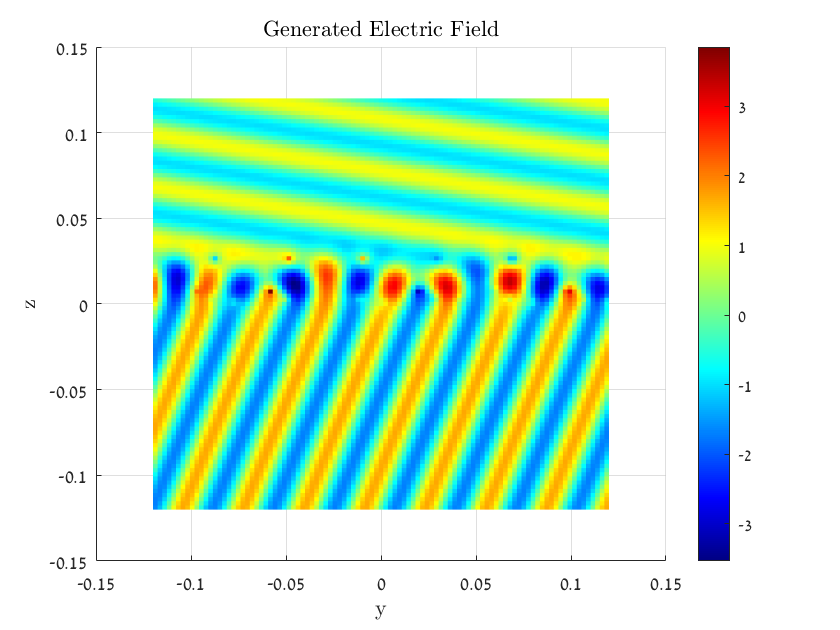


M = 100; %plot resolution
y = linspace(-4*lambda,4*lambda, M)'; % colum vector
z = linspace(-4*lambda,4*lambda, M); % row vector
[TotalElectricFieldMatrix, GeneratedElectricFieldMatrix] = ElectricFieldYZ(best.Is,best.Ds,best.Hs,k,Lambda,y,z,theta_in,Ein,N,eta,theta_out);
PlotField(GeneratedElectricFieldMatrix,y,z,'Generated Electric Field');

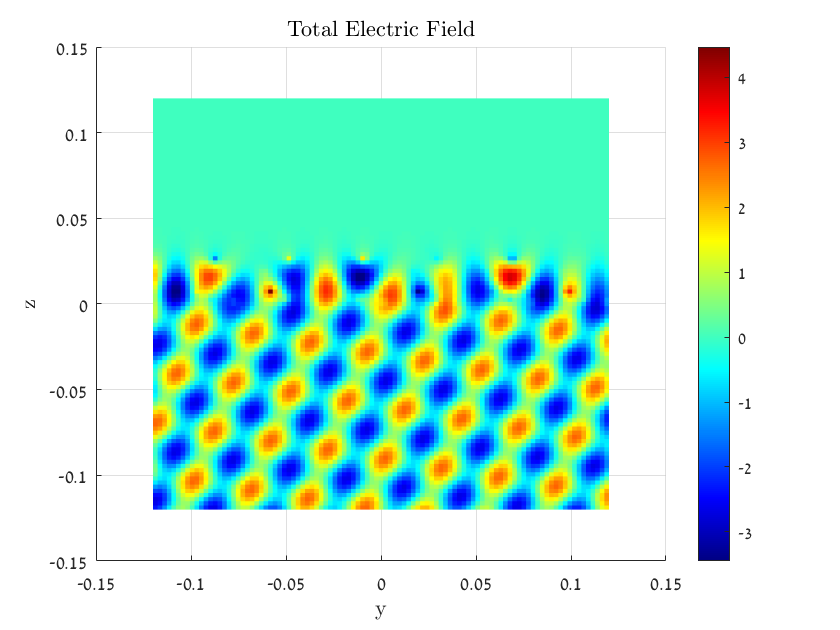

PlotField(TotalElectricFieldMatrix,y,z,'Total Electric Field');

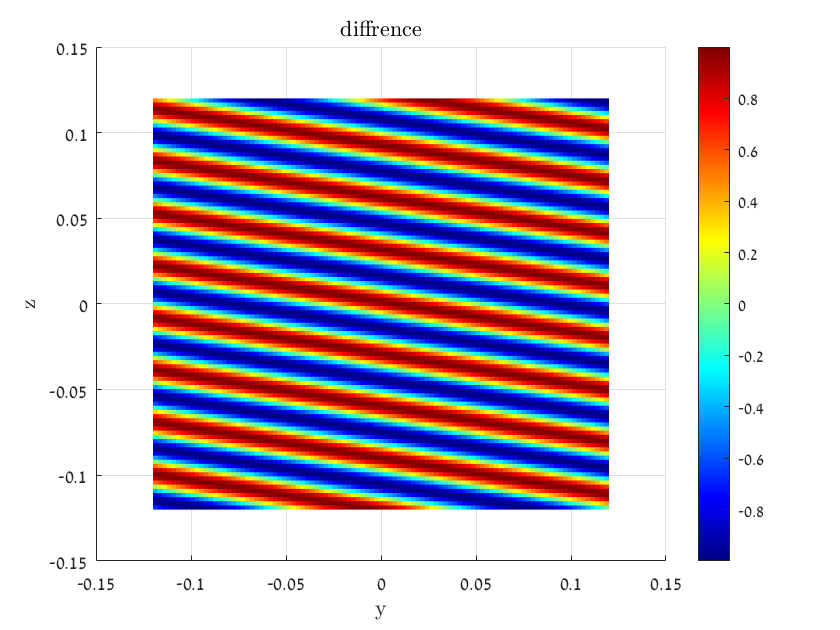

PlotField(TotalElectricFieldMatrix-GeneratedElectricFieldMatrix,y,z,'diffrence');

## normalization

UnitI=Lambda/eta*Ein;
IsNorm=best.Is/UnitI;
DsNorm=best.Ds/Lambda;
HsNorm=best.Hs/Lambda;
PowerIn=1/2/eta*Ein^2*Lambda*cosin;
PowerLost=(1/2*abs(best.Is).^2).*real(best.Zs);
NormPowerLost=PowerLost/PowerIn;
NormCopperPowerLost=best.CopperPowerLost./PowerIn;
NormZs=best.Zs*UnitI;

## optimization function

function f = objectiveFcn(optimInput)

load('var.mat');
% Edit the lines below with your calculation

Ds= [0 optimInput(1:5)];
Hs= [0 optimInput(6:10)];
Is = FindCurrents(Ds,Hs,Lambda,Ein,Eout,Zin,Zout,theta_in,theta_out,k,phi);
Fields = FindElectricFiield(Lambda,k,eta,theta_in,theta_out,Ein,Ds,Hs,Is,reff,N,'Poisson');
Zs= Fields./Is;
f= sum(abs((1/2*abs(Is).^2).*real(Zs)))+weigt*sum(abs((1/2*abs(Is).^2).*deltaRes));% minimum power lost (\gain)
%f= sum(abs(real(Zs)./imag(Zs)));
end


## costrains


function [c,ceq] = constraintFcn(optimInput)
load('var.mat');

% Note, if no equality constraints, specify ceq = []
D2 = optimInput(1);
D3 = optimInput(2);
D4 = optimInput(3);
D5 = optimInput(4);
D6= optimInput(5);
H2 = optimInput(6);
H3 = optimInput(7);
H4 = optimInput(8);
H5 = optimInput(9);
H6 = optimInput(10);


c(1) = H2 - H3;
c(2) = H3 - H4;
c(3) = H4 - H5;
c(4) = H5 - H6;
c(5) = - H2;
c(6) = - D2;
c(7) = - D3;
c(8) = - D4;
c(9) = - D5;
c(10) = - D6;
c(11) = D2 - Lambda;
c(12) = D3 - Lambda;
c(13) = D4 - Lambda;
c(14) = D5 - Lambda;
c(15) = D6 - Lambda;
c(16) = H6 - lambda;
ceq = [];
end


